Beta = [10; 28; 8/3]

Beta =    10.0000
   28.0000
    2.6667



x0 = [0; 1; 20]

x0 =      0
     1
    20


dt = 0.001;
tspan = dt:dt:50;
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));


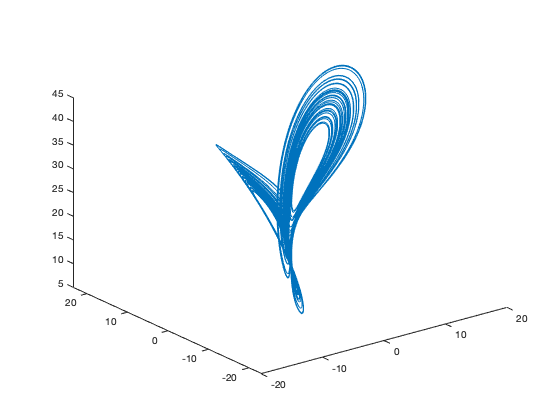

[t,x]=ode45(@(t,x) lorenz(t,x,Beta),tspan,x0,options);
plot3(x(:,1),x(:,2),x(:,3));